# Clutering Independent Trials Test File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 26/10/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

**NOTE: **To maximise the efficiency of clustering algorithms, avoid running the graph-generating code. This ensures that the JIT (Just-In-Time) compiler dedicates its efforts to optimizing the clustering code. Although JIT compilation introduces initial overhead during code execution, its primary advantage is optimizing frequently executed sections of the code. The JIT compiler selectively compiles 'hotspots' based on runtime profiling information, adapting the code to the runtime environment and enhancing subsequent executions.

**Estimate K, the number of independent trails from the M trails:**

-  Determine the distance correlation matrix of the M strategies

-  Apply K-Means clustering to the matrix

- Improve the clustering algorithm by choosing the optimal $K$ clusters using the silhouette score.

- Assess the quality $q$ of the clusters and re-cluster if necessary.

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Add path to backtestedPortfolio object: 

addpath '/Users/Ninamatthews/Documents/MATLAB/STA5000W DISSERTATION Code/OOP'

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path7

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

# TEST CASE: 125 simulated paths per Portfolio

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

load DATA-SIM_TC-125_BKTST-PERFORMANCE-M-CELL_ARR.mat

## 3.  Distance correlation matrix of the M strategies

### 3.1 Extract realised returns from the simulation array

%%%%%%%% MV Simulations %%%
% Initialize an empty T x M timetable
M = length(TCpar_data_processing_config_sim_cellArr);
T = length(TCpar_data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);
TC_MV_simulation_RealisedRet_TT = timetable(TCpar_data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);

% Iterate through the cells in the cell array
for m = 1:M
    % Extract the T x 1 double object from the cell
    data = TCpar_data_processing_config_sim_cellArr{m}.Realised_tsPRet_TT.("MVSR max");
    
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    TC_MV_simulation_RealisedRet_TT = addvars(TC_MV_simulation_RealisedRet_TT, data);
end

TC_MV_simulation_RealisedRet_TT.Properties.Description =  "Realised Returns extracted from MV optimisations run over " + num2str(M) + " trials. Frequency: MONTHLY. Last updated: " + datestr(now, 'yyyy-mm-dd') + ". Intended storage: cell array along with HRP realised returns in intended file name: DATA-SIM-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat";

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

%%%%%%%% HRP Simulations %%%
TC_HRP_simulation_RealisedRet_TT = timetable(TCpar_data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);

% Iterate through the cells in the cell array
for m = 1:M
    % Extract the T x 1 double object from the cell
    data = TCpar_data_processing_config_sim_cellArr{m}.Realised_tsPRet_TT.("HRP");
    
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    TC_HRP_simulation_RealisedRet_TT = addvars(TC_HRP_simulation_RealisedRet_TT, data);
end

TC_HRP_simulation_RealisedRet_TT.Properties.Description = "Realised Returns extracted from HRP optimisations run over " + num2str(M) + " trials. Frequency: MONTHLY. Last updated: " + datestr(now, 'yyyy-mm-dd') + ". Intended storage: cell array along with MV realised returns in intended file name: DATA-SIM-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat";


% Store Realised Returns in single cell array for convenience
TC_data_processing_sim_RealisedRet_cellArr = cell(2,2);
TC_data_processing_sim_RealisedRet_cellArr{1,1} = "MV Sim RealisedRet TT";
TC_data_processing_sim_RealisedRet_cellArr{2,1} = TC_MV_simulation_RealisedRet_TT;
TC_data_processing_sim_RealisedRet_cellArr{1,2} = "HRP Sim RealisedRet TT";
TC_data_processing_sim_RealisedRet_cellArr{2,2} = TC_HRP_simulation_RealisedRet_TT;

**SAVE MV & HRP Simulated Realised Returns:**

sim_filename = 'DATA-SIM_TC-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat';
save(fullfile(dataExportpath,sim_filename),'TC_data_processing_sim_RealisedRet_cellArr');

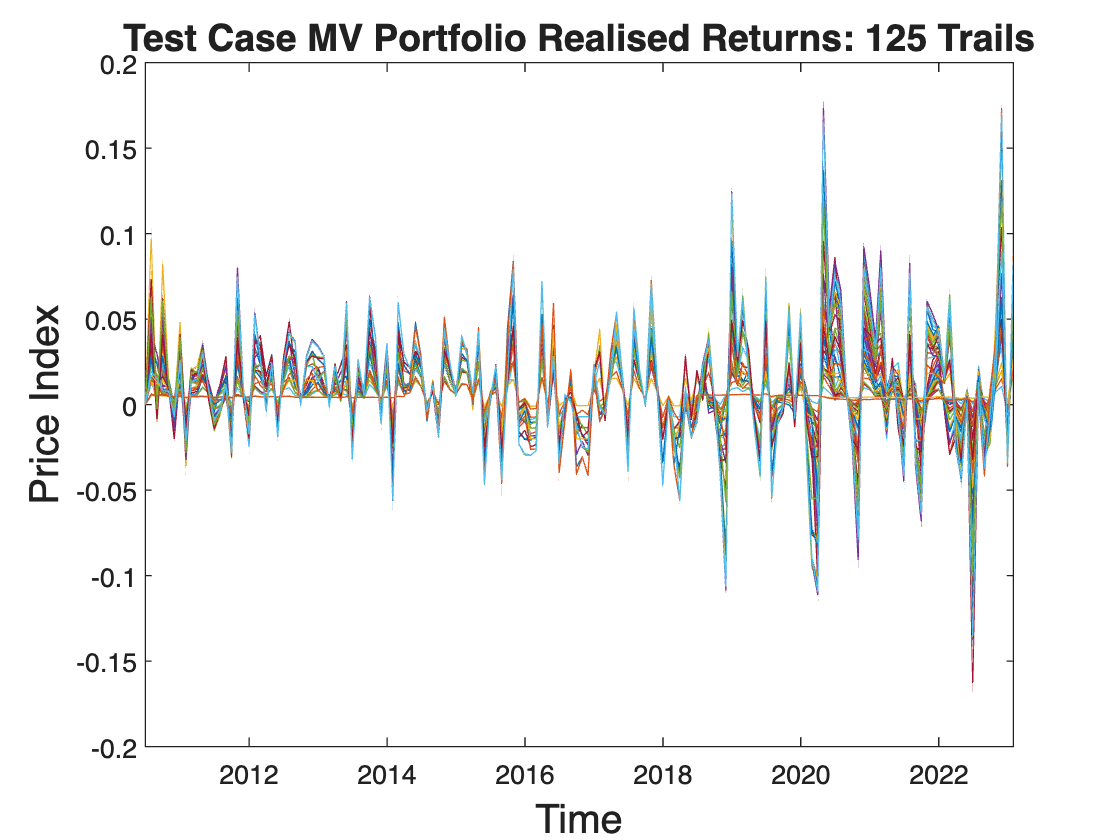

% Assuming myTimetable is your timetable object
figure; % Create a new figure

myTimetable = TC_data_processing_sim_RealisedRet_cellArr{2,1};

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
   title(['Test Case MV Portfolio Realised Returns: ',num2str(width(myTimetable)), ' Trails'],'FontSize', 14);
    xlabel('Time','FontSize', 15);
    ylabel('Price Index','FontSize', 15);
    hold on; % Hold for overlaying plots
end


% Release hold so that future plots won't overlay
hold off;

#### Bollinger Bands for upper and lower bands

T_MV = TC_data_processing_sim_RealisedRet_cellArr{2,1};
[middleMV,upperMV,lowerMV]= bollinger(T_MV);

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 800, 600]);

% Loop through variables and plot Bollinger Bands
for i = 1:width(middleMV)
    % Plot upper band in red
    plot(upperMV.Time, upperMV{:, i}, 'r', 'DisplayName', ['Upper Band - Var', num2str(i)]);
    hold on;

    % Plot lower band in blue
    plot(lowerMV.Time, lowerMV{:, i}, 'b', 'DisplayName', ['Lower Band - Var', num2str(i)]);
end

% Customize the plot as needed
title('MV Bollinger Bands Overlay Plot', 'FontSize', 16);
xlabel('Time', 'FontSize', 15);
ylabel('Value', 'FontSize', 15);
% legend('show'); % Show the legend

hold off; % Release the hold

T_HRP = TC_data_processing_sim_RealisedRet_cellArr{2,2};
[middleHRP,upperHRP,lowerHRP]= bollinger(T_HRP);

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 800, 600]);

% Loop through variables and plot Bollinger Bands
for i = 1:width(middleHRP)
    % Plot upper band in red
    plot(upperHRP.Time, upperHRP{:, i}, 'r', 'DisplayName', ['Upper Band - Var', num2str(i)]);
    hold on;

    % Plot lower band in blue
    plot(lowerHRP.Time, lowerHRP{:, i}, 'b', 'DisplayName', ['Lower Band - Var', num2str(i)]);
end

% Customize the plot as needed
title('HRP Bollinger Bands Overlay Plot', 'FontSize', 16);
xlabel('Time', 'FontSize', 15);
ylabel('Value', 'FontSize', 15);
% legend('show'); % Show the legend

hold off; % Release the hold

### 3.2 Correlation matrix of the realised returns:

TC_MV_sim_corMatrix = corrcoef(table2array(TC_data_processing_sim_RealisedRet_cellArr{2,1}));
TC_HRP_sim_corMatrix = corrcoef(table2array(TC_data_processing_sim_RealisedRet_cellArr{2,2}));

## 4. Test function components:

- base cluster function

- top level function

- make new output fn

- IVP min var allocation

n_init = 3;
max_K = 3;
TC_MV_sim_corMatrix_table = array2table(TC_MV_sim_corMatrix);
TC_HRP_sim_corMatrix_table = array2table(TC_HRP_sim_corMatrix);

### 4.1 MV NON-Parellised

tic
[TC_MVcorr, TC_MVclstrs2, TC_MVsilh2] = clusterKMeansBase(TC_MV_sim_corMatrix, 30, 30);
toc

Elapsed time is 1.940857 seconds.


TC_MVclstrs2


TC_MVclstrs2 =

  dictionary (double ⟼ cell) with 8 entries:

    1 ⟼ {1×20 cell}
    2 ⟼ {1×5 cell}
    3 ⟼ {1×4 cell}
    4 ⟼ {1×36 cell}
    5 ⟼ {1×16 cell}
    6 ⟼ {1×12 cell}
    7 ⟼ {1×8 cell}
    8 ⟼ {1×24 cell}



### 4.1 HRP NON-Parellised

tic
[TC_HRPcorr2, TC_HRPclstrs2, TC_HRPsilh2] = clusterKMeansBase(TC_HRP_sim_corMatrix, 30, 30);
toc

Elapsed time is 1.777042 seconds.


TC_HRPclstrs2


TC_HRPclstrs2 =

  dictionary (double ⟼ cell) with 12 entries:

    1  ⟼ {1×20 cell}
    2  ⟼ {1×4 cell}
    3  ⟼ {1×4 cell}
    4  ⟼ {1×20 cell}
    5  ⟼ {1×4 cell}
    6  ⟼ {1×20 cell}
    7  ⟼ {1×20 cell}
    8  ⟼ {1×20 cell}
    9  ⟼ {1×4 cell}
    10 ⟼ {1×4 cell}
    11 ⟼ {1×4 cell}
    12 ⟼ {1×1 cell}



### 4.2 Test clusering with parellel functionality

% stream = RandStream('mlfg6331_64');  % Random number stream
% options = statset('UseParallel',1,'UseSubstreams',1,...
%     'Streams',stream);
% tic
% [par_TC_MVcorr1, par_TC_MVclstrs, par_TC_MVsilh] = clusterKMeansBase(TC_MV_sim_corMatrix, 6, 6,options);
% toc


Test top level functions:

[TC_HRP_Top_corr,TC_HRP_Top_clstrs,TC_HRP_Top_silh] = clusterKMeansTop(TC_HRP_sim_corMatrix, 30, 30)

CALL MAIN
Else entered
Before recursive call
CALL MAIN
Else entered
Before recursive call
CALL MAIN
Else entered
Before recursive call
CALL MAIN
End recursive call


CALL 1:

max_K = 30;
n_init = 30;
corr0 = TC_HRP_sim_corMatrix;
%% Perform base cluster to initialise E[K]
[corr1, clstrs, silh] = clusterKMeansBase(corr0, max_K, n_init,[]);
% Calc Tstats per cluster
clusterTstats = dictionary;

for i = 1:length(keys(clstrs))
    % Turn each string element in cells to a double
    series_indx = cellfun(@(x)str2double(x), clstrs{i});
    % Calculate each cluster's Tstat
    clusterTstats{i} = mean(silh(series_indx)) / std(silh(series_indx));
end

% calc Average tstat across clusters
tStatMean = mean(cell2mat(values(clusterTstats)));

%% extract cluster # that have tstat less than average
redoClusters = find(cell2mat(values(clusterTstats)) < tStatMean);


%% Recluster clusters with low tstats
if length(redoClusters) <= 2
    corrNew = corr1;
    clstrsNew = clstrs;
    silhNew = silh;
    return;
else
    disp("Else entered")
    % Extract all idx values from redo clusters
    keysRedo = [];
    for i = redoClusters
        keysRedo = [keysRedo, clstrs{i}];
    end
    % convert char to double
    keysRedo = cellfun(@(x)str2double(x), keysRedo);
    % Index out the correlations in redo clusters to recluster
    corrTmp = corr0(keysRedo, keysRedo);

    %%%% NOTE: max_K can't exceed number of paths
    if max_K > size(corrTmp,1)
        max_K = size(corrTmp,1)-1;
    end

    % [~, clstrs2, ~] = clusterKMeansTop(corrTmp, max_K, n_init);
end

Else entered


CALL 2:

%% Perform base cluster to initialise E[K]
[corr1, clstrs, silh] = clusterKMeansBase(corrTmp, max_K, n_init,[]);
% Calc Tstats per cluster
clusterTstats = dictionary;

for i = 1:length(keys(clstrs))
    % Turn each string element in cells to a double
    series_indx = cellfun(@(x)str2double(x), clstrs{i});
    % Calculate each cluster's Tstat
    clusterTstats{i} = mean(silh(series_indx)) / std(silh(series_indx));
end

% calc Average tstat across clusters
tStatMean = mean(cell2mat(values(clusterTstats)));

%% extract cluster # that have tstat less than average
redoClusters = find(cell2mat(values(clusterTstats)) < tStatMean);

%% Recluster clusters with low tstats
if length(redoClusters) <= 2
    corrNew = corr1;
    clstrsNew = clstrs;
    silhNew = silh;
    return;
else
    disp("Else entered")
    % Extract all idx values from redo clusters
    keysRedo = [];
    for i = redoClusters
        keysRedo = [keysRedo, clstrs{i}];
    end
    % convert char to double
    keysRedo = cellfun(@(x)str2double(x), keysRedo);
    % Index out the correlations in redo clusters to recluster
    corrTmp = corr0(keysRedo, keysRedo);

    %%%% NOTE: max_K can't exceed number of paths
    if max_K > size(corrTmp,1)
        max_K = size(corrTmp,1)-1;
    end
end

Else entered


CALL 3:

%% Perform base cluster to initialise E[K]
[corr1, clstrs, silh] = clusterKMeansBase(corrTmp, max_K, n_init,[]);
% Calc Tstats per cluster
clusterTstats = dictionary;

for i = 1:length(keys(clstrs))
    % Turn each string element in cells to a double
    series_indx = cellfun(@(x)str2double(x), clstrs{i});
    % Calculate each cluster's Tstat
    clusterTstats{i} = mean(silh(series_indx)) / std(silh(series_indx));
end

% calc Average tstat across clusters
tStatMean = mean(cell2mat(values(clusterTstats)));

%% extract cluster # that have tstat less than average
redoClusters = find(cell2mat(values(clusterTstats)) < tStatMean);

%% Recluster clusters with low tstats
if length(redoClusters) <= 2
    corrNew = corr1;
    clstrsNew = clstrs;
    silhNew = silh;
    return;
else
    disp("Else entered")
    % Extract all idx values from redo clusters
    keysRedo = [];
    for i = redoClusters
        keysRedo = [keysRedo, clstrs{i}];
    end
    % convert char to double
    keysRedo = cellfun(@(x)str2double(x), keysRedo);
    % Index out the correlations in redo clusters to recluster
    corrTmp = corr0(keysRedo, keysRedo);

    %%%% NOTE: max_K can't exceed number of paths
    if max_K > size(corrTmp,1)
        max_K = size(corrTmp,1)-1;
    end
end

# FULL CASE: 3375 simulated paths per Portfolio

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

load DATA-SIM-3375_BKTST-PERFORMANCE-M-CELL_ARR.mat

## 3.  Distance correlation matrix of the M strategies

### 3.1 Extract realised returns from the simulation array

%%%%%%%% MV Simulations %%%
% Initialize an empty T x M timetable
M = length(data_processing_config_sim_cellArr);
T = length(data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);
MV_simulation_RealisedRet_TT = timetable(data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);

% Iterate through the cells in the cell array
for m = 1:M
    % Extract the T x 1 double object from the cell
    data = data_processing_config_sim_cellArr{m}.Realised_tsPRet_TT.("MVSR max");
    
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    MV_simulation_RealisedRet_TT = addvars(MV_simulation_RealisedRet_TT, data);
end

MV_simulation_RealisedRet_TT.Properties.Description =  "Realised Returns extracted from MV optimisations run over " + num2str(M) + " trials. Frequency: MONTHLY. Last updated: " + datestr(now, 'yyyy-mm-dd') + ". Intended storage: cell array along with HRP realised returns in intended file name: DATA-SIM-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat";

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

%%%%%%%% HRP Simulations %%%
HRP_simulation_RealisedRet_TT = timetable(data_processing_config_sim_cellArr{1}.Realised_tsPRet_TT.Time);

% Iterate through the cells in the cell array
for m = 1:M
    % Extract the T x 1 double object from the cell
    data = data_processing_config_sim_cellArr{m}.Realised_tsPRet_TT.("HRP");
    
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    HRP_simulation_RealisedRet_TT = addvars(HRP_simulation_RealisedRet_TT, data);
end

HRP_simulation_RealisedRet_TT.Properties.Description = "Realised Returns extracted from HRP optimisations run over " + num2str(M) + " trials. Frequency: MONTHLY. Last updated: " + datestr(now, 'yyyy-mm-dd') + ". Intended storage: cell array along with MV realised returns in intended file name: DATA-SIM-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat";


% Store Realised Returns in single cell array for convenience
data_processing_sim_RealisedRet_cellArr = cell(2,2);
data_processing_sim_RealisedRet_cellArr{1,1} = "MV Sim RealisedRet TT";
data_processing_sim_RealisedRet_cellArr{2,1} = MV_simulation_RealisedRet_TT;
data_processing_sim_RealisedRet_cellArr{1,2} = "HRP Sim RealisedRet TT";
data_processing_sim_RealisedRet_cellArr{2,2} = HRP_simulation_RealisedRet_TT;

**SAVE MV & HRP Simulated Realised Returns:**

sim_filename = 'DATA-SIM-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat';
save(fullfile(dataExportpath,sim_filename),'data_processing_sim_RealisedRet_cellArr');

% Assuming myTimetable is your timetable object
figure; % Create a new figure

myTimetable = data_processing_sim_RealisedRet_cellArr{2,1};
% Iterate through each variable in the timetable
for i = 1:5
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
    title(myTimetable.Properties.VariableNames{i});
    xlabel('Time');
    ylabel('Variable Value');
    
    hold on; % Hold for overlaying plots
end


% Release hold so that future plots won't overlay
hold off;


### 6.1 Visualise MV Realised Returns

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(data_processing_sim_RealisedRet_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(data_processing_sim_RealisedRet_cellArr{2,i}.Time, data_processing_sim_RealisedRet_cellArr{2,i});  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['Test Case MV Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 14);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

TC_MV_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

### 3.2 Correlation matrix of the realised returns:

MV_sim_corMatrix = corrcoef(table2array(data_processing_sim_RealisedRet_cellArr{2,1}));
HRP_sim_corMatrix = corrcoef(table2array(data_processing_sim_RealisedRet_cellArr{2,2}));

## 4. Test function components:

- base cluster function

- top level function

- make new output fn

- IVP min var allocation

n_init = 3;
max_K = 3;
MV_sim_corMatrix_table = array2table(MV_sim_corMatrix);
HRP_sim_corMatrix_table = array2table(HRP_sim_corMatrix);

### 4.1 Base KMean Clustering Fn (1st Pass at E[K]) 

#### 4.1.1  *** HRP *** Max number of clusters = 6

tic
[Full_test_HRPcorr1, Full_test_HRPclstrs, Full_test_HRPsilh] = clusterKMeansBase(HRP_sim_corMatrix, 6, 6);
toc

**Results** in 4 clusters being chosen.

#### 4.1.1  *** MV *** Max number of clusters = 6

tic
[Full_test_MVcorr1, Full_test_MVclstrs, Full_test_MVsilh] = clusterKMeansBase(MV_sim_corMatrix, 6, 6);
toc

**Results** in 4 clusters being chosen.

### 4.2 Base KMean Clustering Fn (1st Pass at E[K]) 

#### 4.2.1  *** HRP ** Max number of clusters = 10

tic
[Full_test_HRPcorr2, Full_test_HRPclstrs2, Full_test_HRPsilh2] = clusterKMeansBase(HRP_sim_corMatrix, 10, 6);
toc

**Results** in 4 clusters being chosen.

### 4.2 Base KMean Clustering Fn (1st Pass at E[K]) 

#### 4.2.1  *** HRP *** Max number of clusters = 10

tic
[Full_test_HRPcorr3, Full_test_HRPclstrs3, Full_test_HRPsilh3] = clusterKMeansBase(MV_sim_corMatrix, 6, 10);
toc

**Results** in 4 clusters being chosen.

#### 4.1.1 HRP base clustering  **************%%%%%%%%%%%%%%%%%%%

profile on
[full_HRP_corr, full_HRP_clstrs, full_HRP_silh] = clusterKMeansBase(HRP_sim_corMatrix, 30, 30)
profile off
profile_HRP = profile("info");

**SAVE MV & HRP Simulated Realised Returns:**

sim_filename = 'full_HRP_corr_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_HRP_corr');

sim_filename = 'full_HRP_clstrs_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_HRP_clstrs');

sim_filename = 'full_HRP_silh_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_HRP_silh');


#### 4.1.2 MV base clustering  **************%%%%%%%%%%%%%%%%%%%

profile on
[full_MV_corr, full_MV_clstrs, full_MV_silh] = clusterKMeansBase(MV_sim_corMatrix, 30, 30)
profile off
profile_MV = profile("info");

**SAVE MV & HRP Simulated Realised Returns:**

sim_filename = 'full_MV_corr_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_MV_corr');

sim_filename = 'full_MV_clstrs_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_MV_clstrs');

sim_filename = 'full_MV_silh_BaseKMeansClustered.mat';
save(fullfile(dataExportpath,sim_filename),'full_MV_silh');

#### 4.1.2 MV base clustering 

max_K = 30;
n_init = 30;
[MVcorr1, MVclstrs, MVsilh] = clusterKMeansBase(MV_sim_corMatrix, max_K, n_init)

clusterTstats = dictionary;

    for i = 1:length(keys(MVclstrs))
        series_indx = cellfun(@(x)str2double(x), MVclstrs{i});
        clusterTstats{i} = mean(MVsilh(series_indx)) / std(MVsilh(series_indx));
    end

    tStatMean = mean(cell2mat(values(clusterTstats)));

    redoClusters = find(cell2mat(values(clusterTstats)) < tStatMean);

Plot the color coded series based on cluster allocation

% % Map it backwards to color code series in plot based on clusters
% % Create a new figure for the plot
% figure('InnerPosition', [100, 100, 600, 600]);
% % Iterate through each timetable in the cell array and plot it
% for i = 1:numel(data_processing_config_sim_cellArr)
%     subplot(1, 1, 1);  % Define the subplot layout as needed
%     %%% IF column index is in cluster 1 plot color = blue, if index in
%     %%% cluster 2, color = 
%     plot(data_processing_config_sim_cellArr{i}.RollingPerformance.Time, data_processing_config_sim_cellArr{i}.RollingPerformance.("HRP"));  % Adjust VariableName1 as needed
%     hold on;
%     i;% Overlay plots on the same axes
% end
% % Customize the plot as needed
% title(['Varying Winsorise std. Exclusively: ',num2str(HRP_winsor_num_configs), ' Trails'],'FontSize', 16);
% xlabel('Time','FontSize', 15);
% ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed
% 
% HRP_Winsor_BCKTST_SIM_Performance_plot = gcf;
% 
% % Release hold so that future plots won't overlay
% hold off; 


format longG
tStatMean

### 4.2 Top Level  KMean Clustering Fn (2nd Pass at E[K])

[HRP_test_corr1, HRP_test_clstrs, HRP_test_silh] = clusterKMeansTop(HRP_sim_corMatrix, 5, 5)

keysRedo = [];
for i = redoClusters
            keysRedo = [keysRedo, MVclstrs{i}];
end
keysRedo = cellfun(@(x)str2double(x), keysRedo);

long 
corrTmp = MV_sim_corMatrix(keysRedo, keysRedo); 

 meanRedoTstat = mean(cell2mat(clusterTstats(redoClusters))); 

[corr2, clstrs2, silh2] = clusterKMeansBase(corrTmp, 30, 3);